*Prepared by *

*Asif Newaz*

*Lecturer, EEE, IUT*

**Case - 01**

fs = 1000;
t = 0:1/fs:1;
x = sin(2*pi*t*3);
x2 = sin(2*pi*t*3) + 0.15*sin(2*pi*t*40);

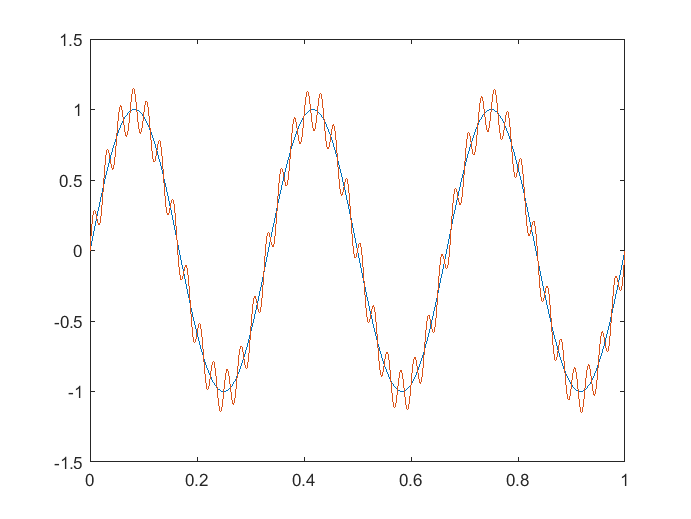

plot (t, x, t, x2)

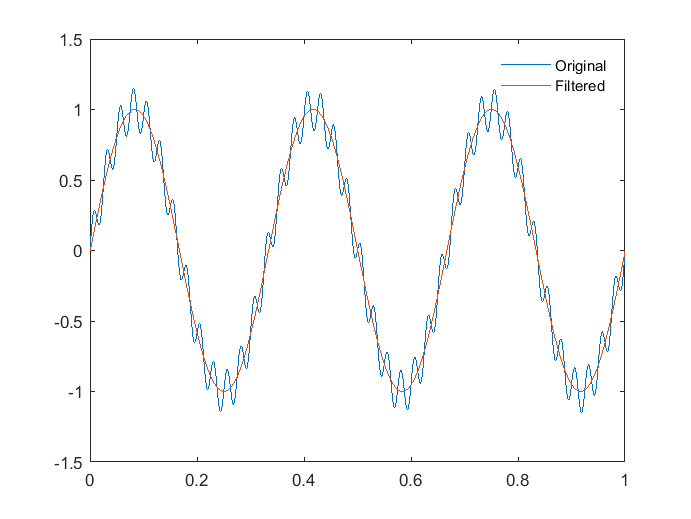

y = medfilt1(x,10);

plot(t,x2, t, y)
legend('Original','Filtered')
legend('boxoff')

**Case - 02**

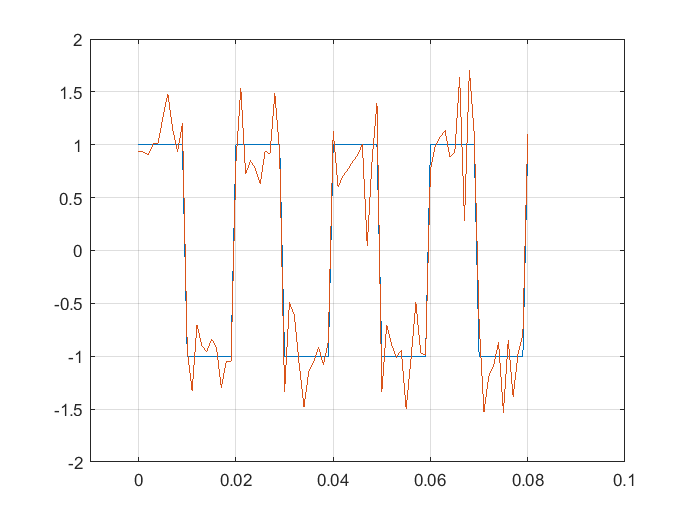

x= 0:0.001:0.08; 
y= square(2*pi*50*x);     
noise = awgn(y,10, 'measured');

plot(x,y, x, noise)
axis([-0.01, 0.1, -2,2])
grid on

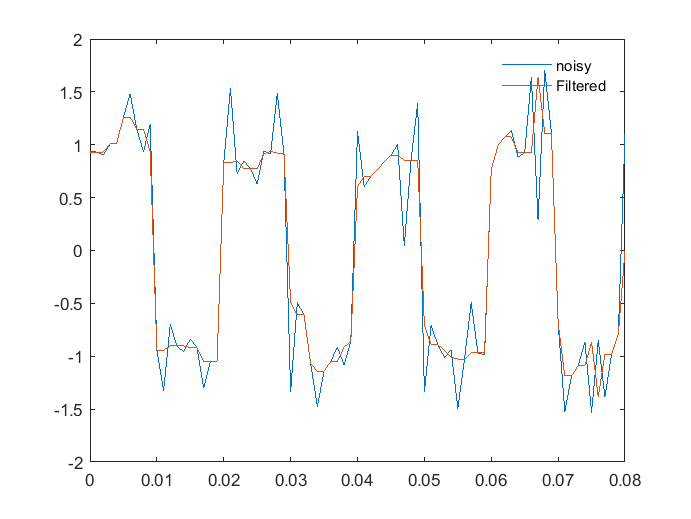

z1= medfilt1(noise);
plot(x, noise,x,z1)
legend('noisy','Filtered')
legend('boxoff')

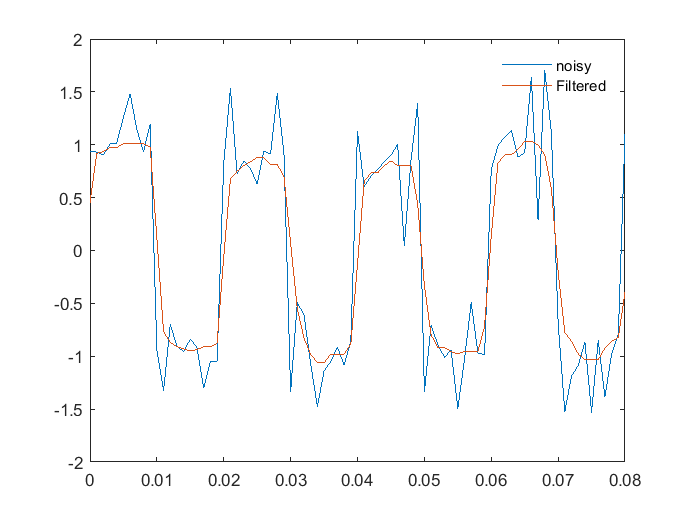

z10= medfilt1(noise, 10);
plot(x, noise,x,z10)
legend('noisy','Filtered')
legend('boxoff')

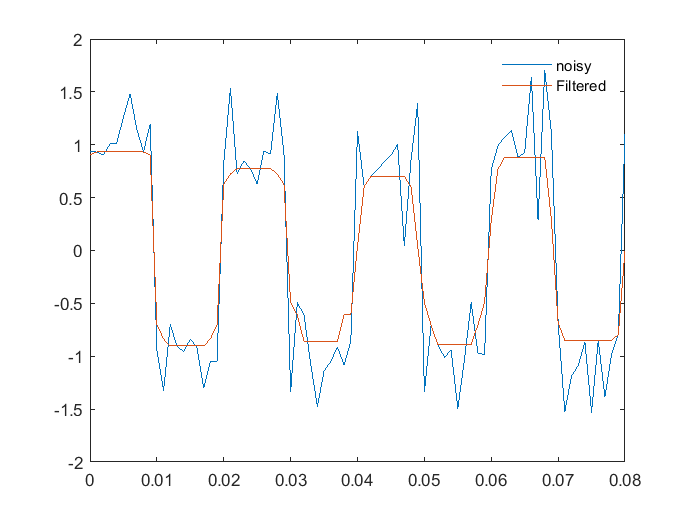

z15= medfilt1(noise, 15);
plot(x, noise,x,z15)
legend('noisy','Filtered')
legend('boxoff')

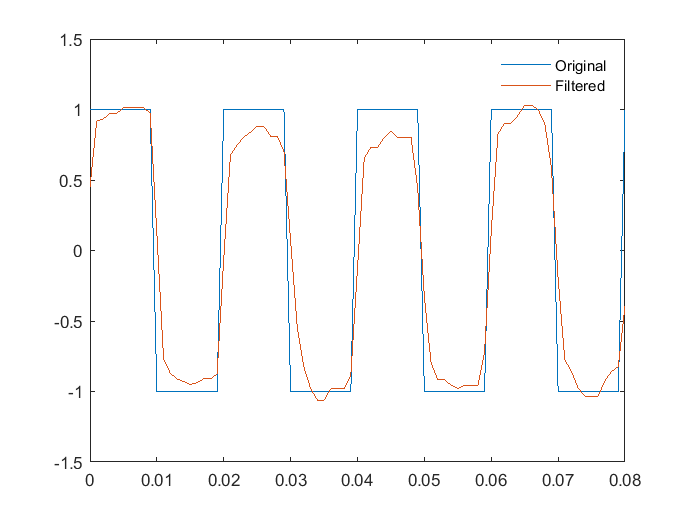

plot(x, y,x,z10)
legend('Original','Filtered')
legend('boxoff')

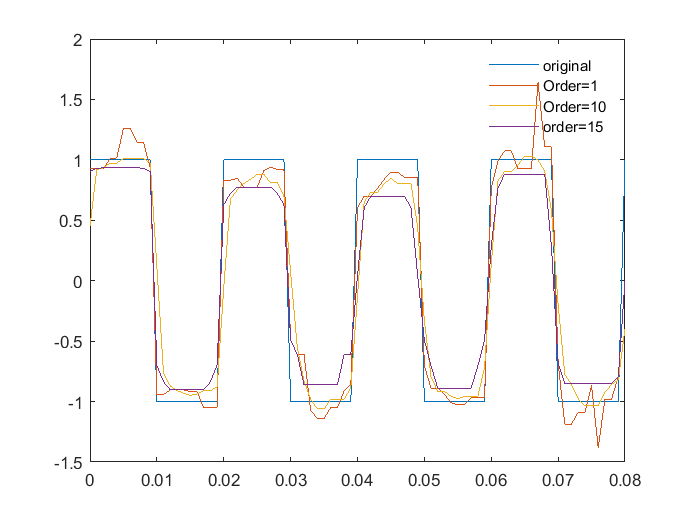

plot(x, y, x, z1,x,z10, x,z15)
legend('original', 'Order=1','Order=10','order=15')
legend('boxoff')

**Hampel filter**

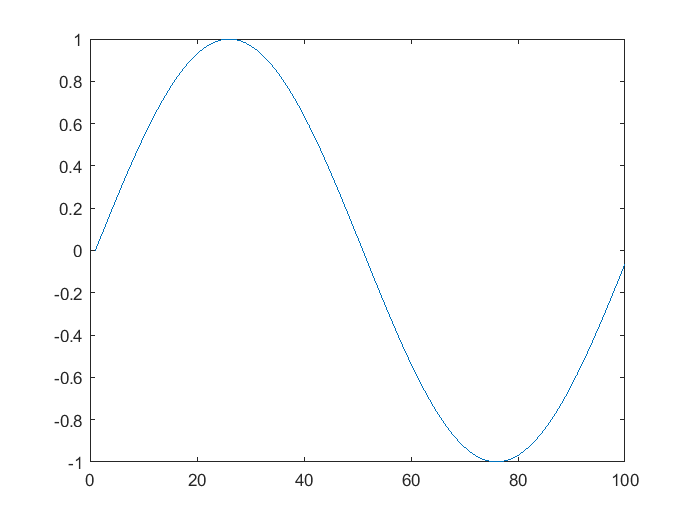

x = sin(2*pi*(0:99)/100);
t = 1:length(x);
plot(t,x)

Let's add some spike in the signal.

x(10)= 3;
x(25)= -2;
x(60:62) = 4;

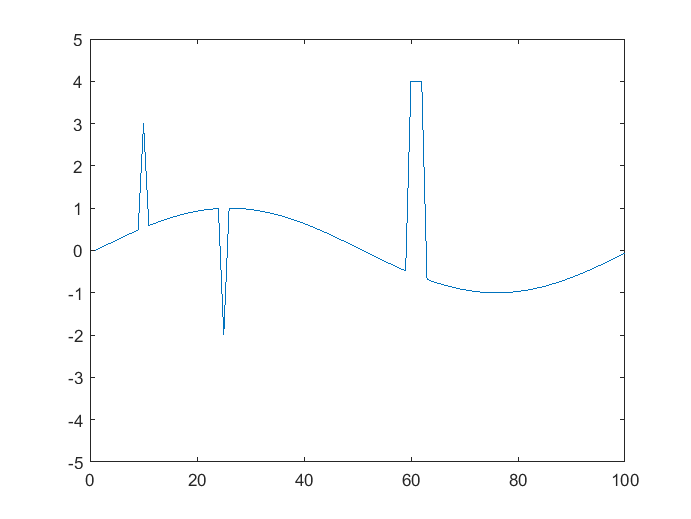

plot(t,x)
axis([0,100,-5,5])

[y,i,xmedian,xsigma] = hampel(x)

y =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5878    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9921    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


i = 1×100 logical array
   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


xmedian =     0.0941    0.1253    0.1564    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5878    0.6374    0.6845    0.7290    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9511    0.9686    0.9823    0.9921    0.9921    0.9921    0.9823    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


xsigma =     0.0924    0.0927    0.1378    0.1803    0.1771    0.1731    0.1685    0.1731    0.1685    0.1572    0.1357    0.1275    0.1187    0.1187    0.1094    0.0998    0.0897    0.0793    0.0685    0.0575    0.0463    0.0463    0.0349    0.0233    0.0117    0.0117    0.0117    0.0233    0.0233    0.0349    0.0463    0.0575    0.0685    0.0793    0.0897    0.0998    0.1094    0.1187    0.1275    0.1357    0.1435    0.1506    0.1572    0.1632    0.1685    0.1731    0.1771    0.1803    0.1829    0.1847


% i locates the outlier points

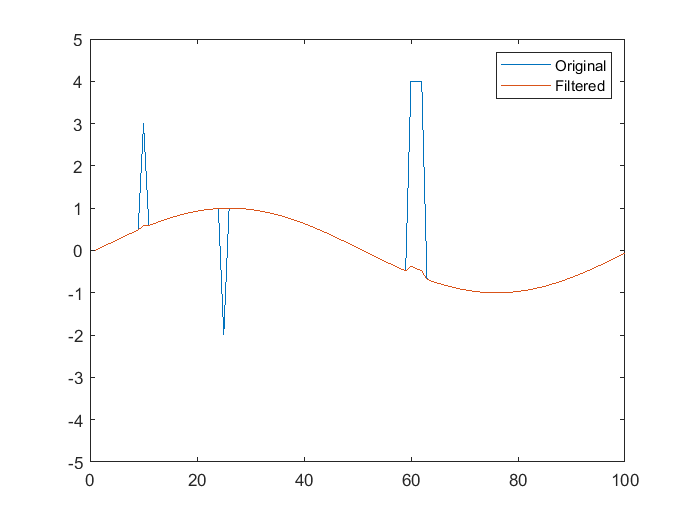

plot(t,x,t,y)
axis([0,100,-5,5])
legend('Original','Filtered')

nnz(i)

ans = 5

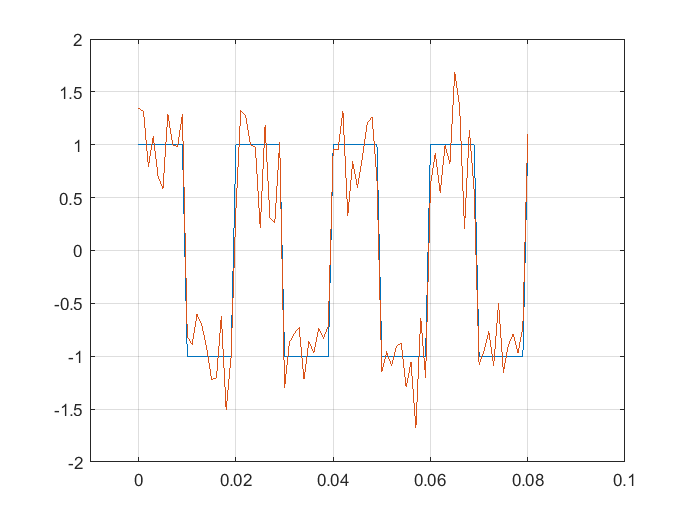

x= 0:0.001:0.08; 
y= square(2*pi*50*x);     
noise = awgn(y,10, 'measured');

plot(x,y, x, noise)
axis([-0.01, 0.1, -2,2])
grid on

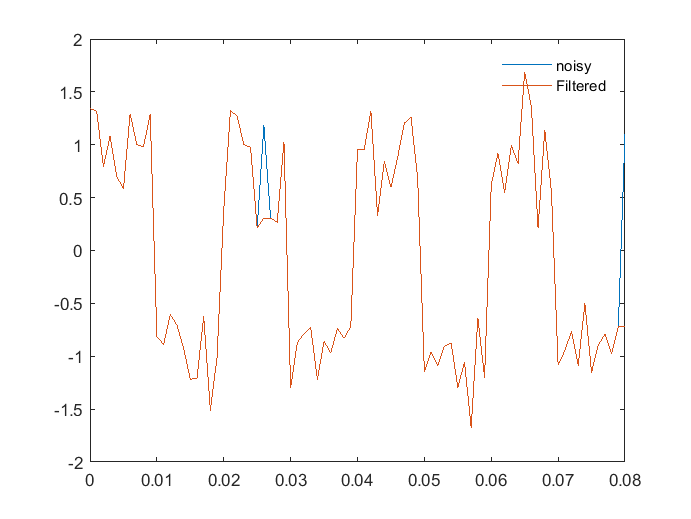

z= hampel(noise,2);
plot(x, noise,x,z)
legend('noisy','Filtered')
legend('boxoff')